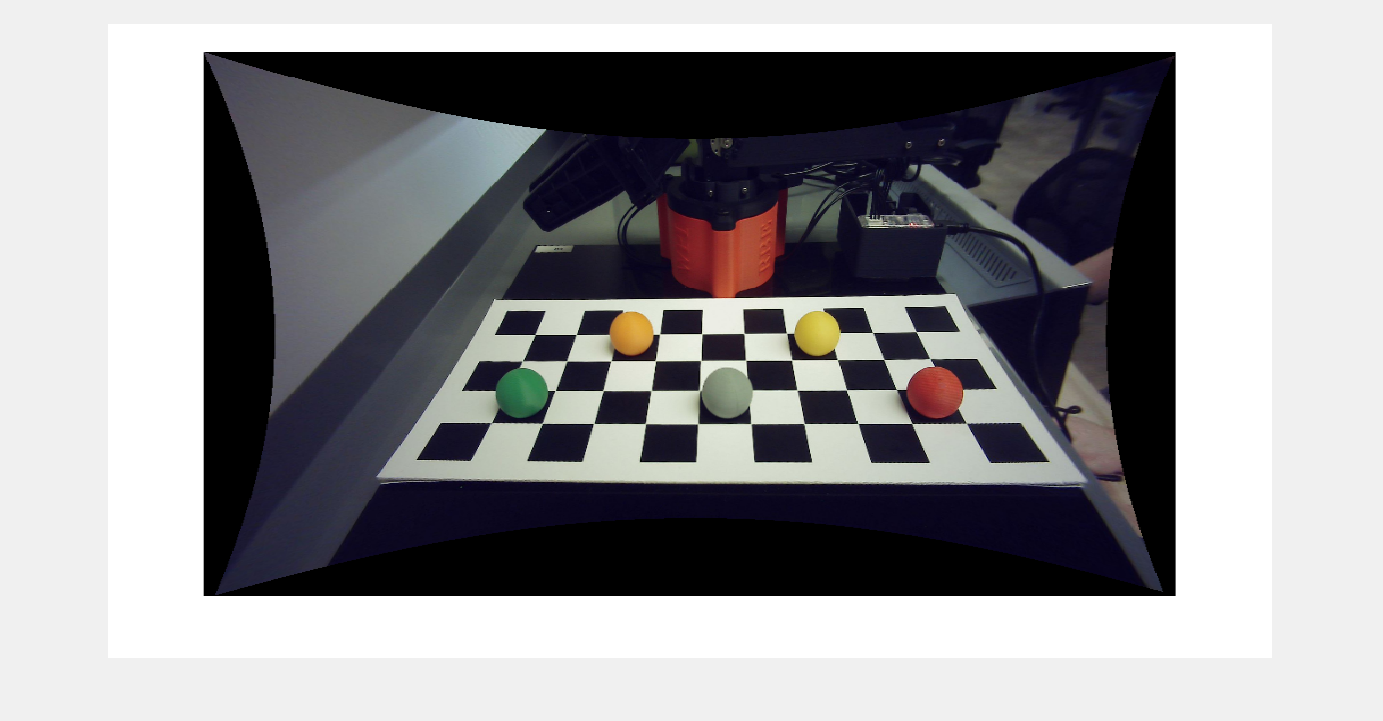

Put Ball On


clear 
clc
close all

image = imread("ALLCOLORS2.png");
imshow(image);
[x, y] = ginput(4);
maskPts = [x'; y'];
 try
          disp("Put Ball On");
          pause;      
 end

      
      mask = zeros(size(image, 1), size(image, 2));
      mask = poly2mask(maskPts(1, :), maskPts(2, :), size(image, 1), size(image, 2));
      mask = logical(mask);
      maskedImage = image;
      maskedImage(repmat(~mask, [1, 1, size(image, 3)])) = 0;
      ball = createMask(maskedImage); 
      filledBall = imfill(ball, 'holes');

      ball = logical(ball);
      ballMaskedImage = image;
      
      ballMaskedImage(repmat(~ball, [1, 1, size(image,3)])) = 0;

      L = bwlabel(filledBall);
      stats = regionprops(L, 'Centroid', 'Area');
      validCircles = [];
      for i = 1:length(stats)
        centroid = stats(i).Centroid;
        area = stats(i).Area;
        if area > 1000
            disp(centroid);
            disp(area);
            validCircles = [validCircles; centroid, area];
        end



      end

  417.1374  373.4493



        2139



  528.6504  312.9786



        1496



  625.3631  372.8661



        2002



  716.4379  312.9578



        1610



  835.2035  372.4917



        2349



    colorOfBall = cell(length(validCircles), 1);
    ballColor = cell(length(validCircles), 1);
    for i = 1:length(validCircles)
        hsvImage = rgb2hsv(image);
        [x, y] = meshgrid(1:size(hsvImage, 2), 1:size(hsvImage, 1));
        
        % Extract circle parameters for the current iteration
        centerX = validCircles(i, 1);
        centerY = validCircles(i, 2);
        radius = sqrt(validCircles(i, 3)/pi)/2;
        
        % Create a binary mask for the circle
        maskColor = zeros(size(hsvImage, 1), size(hsvImage, 2));
        maskColor = ((x - centerX).^2 + (y - centerY).^2) <= radius^2;
        maskColor = logical(maskColor);
        % Extract the ROI from the hsvImage
        roiHue = hsvImage(:, :, 1);
        roiSaturation = hsvImage(:, :, 2);
        roiValue = hsvImage(:, :, 3);
        
        roiHue(~maskColor) = 0;
        roiSaturation(~maskColor) = 0;
        roiValue(~maskColor) = 0;
        
        % Calculate the average Hue, Saturation, and Value inside the ROI
        average_hue = mean(roiHue(maskColor));
        average_saturation = mean(roiSaturation(maskColor));
        average_value = mean(roiValue(maskColor));
        
        % Display the average HSV values and debug info
        fprintf('Circle %d: centerX = %d, centerY = %d, radius = %d\n', i, centerX, centerY, radius);
        fprintf('Average HSV for Circle %d: Hue = %.2f, Saturation = %.2f, Value = %.2f\n', i, average_hue, average_saturation, average_value);
        
        % You can also convert the average HSV values back to RGB for visualization.
        average_rgb = hsv2rgb([average_hue, average_saturation, average_value]);
        if(average_hue > 0.4)
            ballColorInput = sprintf('Ball %d Color: Green', i);
            ballColor{i} = sprintf('green');
        else
            ballColorInput = sprintf('Ball %d Color: Yellow', i);
            ballColor{i} = sprintf('yellow');
        end
        colorOfBall{i} = ballColorInput;
        
        
        fprintf('Average RGB for Circle %d: R = %.2f, G = %.2f, B = %.2f\n', i, average_rgb(1), average_rgb(2), average_rgb(3));
    end

Circle 1: centerX = 4.171374e+02, centerY = 3.734493e+02, radius = 1.304669e+01


Average HSV for Circle 1: Hue = 0.40, Saturation = 0.58, Value = 0.48


Average RGB for Circle 1: R = 0.20, G = 0.48, B = 0.31


Circle 2: centerX = 5.286504e+02, centerY = 3.129786e+02, radius = 1.091091e+01


Average HSV for Circle 2: Hue = 0.11, Saturation = 0.72, Value = 0.84


Average RGB for Circle 2: R = 0.84, G = 0.62, B = 0.24


Circle 3: centerX = 6.253631e+02, centerY = 3.728661e+02, radius = 1.262197e+01


Average HSV for Circle 3: Hue = 0.26, Saturation = 0.16, Value = 0.58


Average RGB for Circle 3: R = 0.53, G = 0.58, B = 0.49


Circle 4: centerX = 7.164379e+02, centerY = 3.129578e+02, radius = 1.131900e+01


Average HSV for Circle 4: Hue = 0.15, Saturation = 0.63, Value = 0.82


Average RGB for Circle 4: R = 0.82, G = 0.76, B = 0.30


Circle 5: centerX = 8.352035e+02, centerY = 3.724917e+02, radius = 1.367214e+01


Average HSV for Circle 5: Hue = 0.26, Saturation = 0.67, Value = 0.62


Average RGB for Circle 5: R = 0.38, G = 0.62, B = 0.20


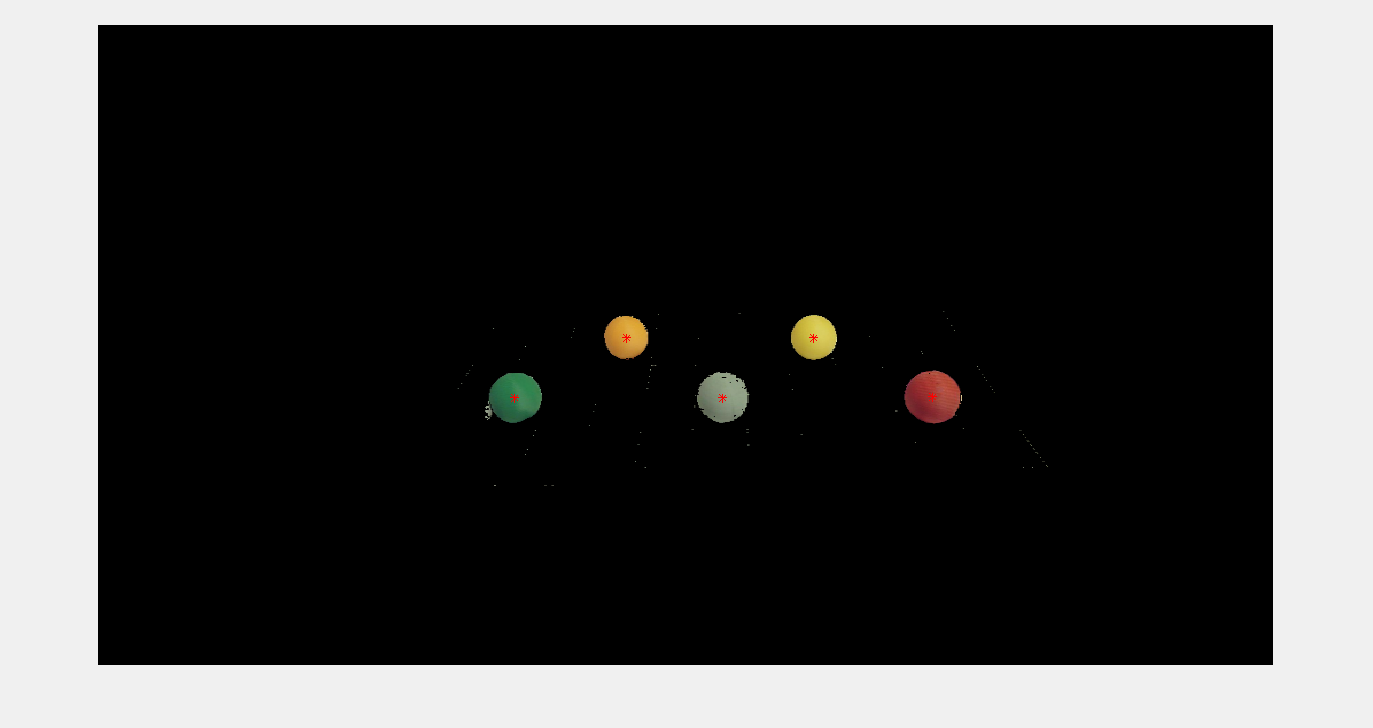


     

      BallOverlayed = image;
      for i = 1:length(validCircles)
          BallOverlayed = insertObjectAnnotation(BallOverlayed, "circle", [validCircles(i, 1:2) sqrt(validCircles(i, 3)/pi)], colorOfBall(i),  LineWidth = 2, TextBoxOpacity=0, TextColor = ballColor(i), Color=ballColor(i));
      end
      
      
%       gray_image = im2gray(maskedImage);
%       bw = gray_image < 50;
%       stats = regionprops("table", bw, "Centroid", ...
%           "MajorAxisLength", "MinorAxisLength");

      %imageWithMask = insertObjectMask(image, maskedImage);
      
      figure(1)
      
      imshow(ballMaskedImage);
      
      hold on
        plot(validCircles(:,1), validCircles(:,2), 'r*')
      hold off

%       hold on
%       
%       hold off
%     r_pos = centers_to_positions(r_pos(1:2)');
      
